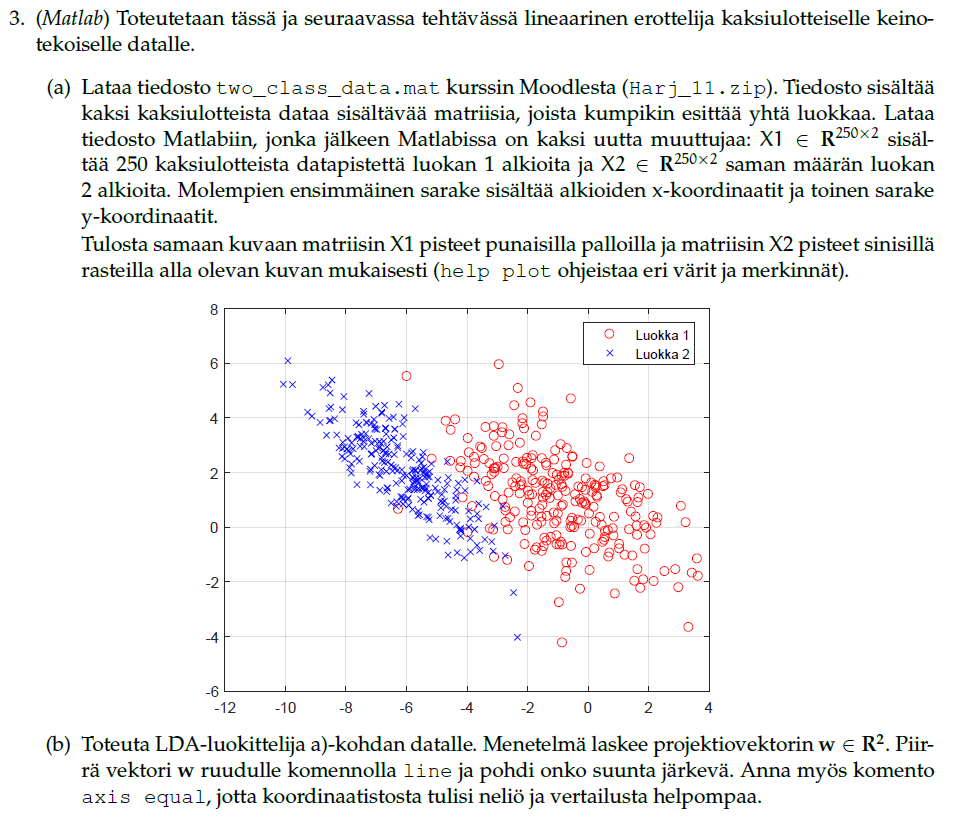

%a
load two_class_data.mat
plot(X1(:,1),X1(:,2),'ro',X2(:,1),X2(:,2),'bx')
legend({'Luokka1','Luokka2'},'Location','northeast')
%b
%w=(cov1+cov2)^-1(odotusarvo1-odotusarvo2)
myy1=mean(X1);
myy2=mean(X2)

myy2 =    -6.0998    2.0525


%w=(myy1-myy2)*inv(cov(X1)-cov(X2))
w=inv(cov(X1)+cov(X2))*transpose(myy1-myy2)

w =     1.3497
    0.7261


X=[w(1,1),-5*w(1,1)]

X =     1.3497   -6.7486


Y=[w(2,1),-5*w(2,1)]

Y =     0.7261   -3.6305


line(X,Y)
axis equal

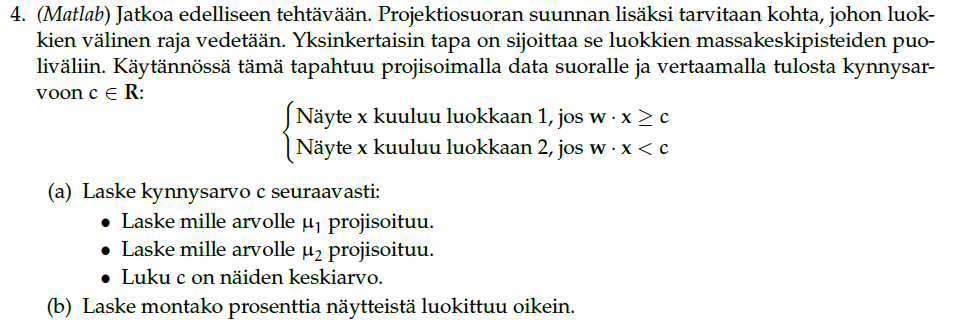

%a
C1=dot(w,myy1)

C1 = -0.5823

C2=dot(w,myy2)

C2 = -6.7427

c=(C1+C2)/2

c = -3.6625

%b
matrix1=zeros(1,250);
matrix2=zeros(1,250);
for i= 1:250;
    %matrix1
    vec=[X1(i,1),X1(i,2)];
    matrix1(1,i)=dot(w,vec);
     %matrix2
    vec2=[X2(i,1),X2(i,2)];
    matrix2(1,i)=dot(w,vec2);
end
A=matrix1>c;
B=matrix2<c;
all=sum(A,'all')+sum(B,'all')

all = 483

all/500

ans = 0.9660

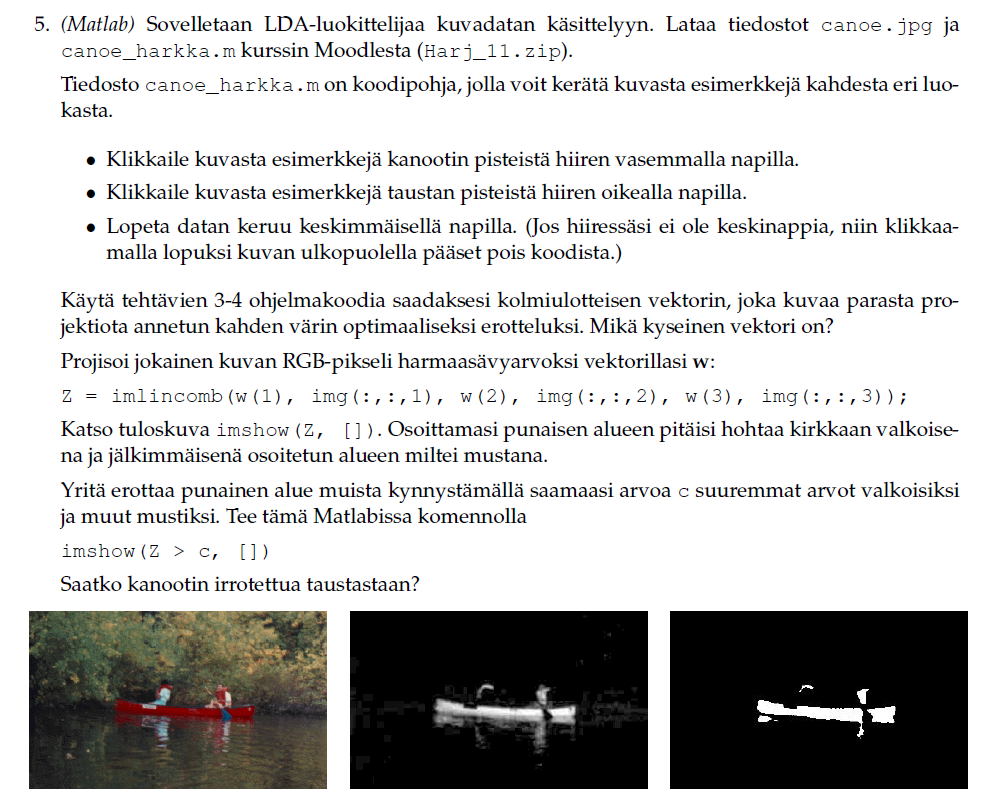

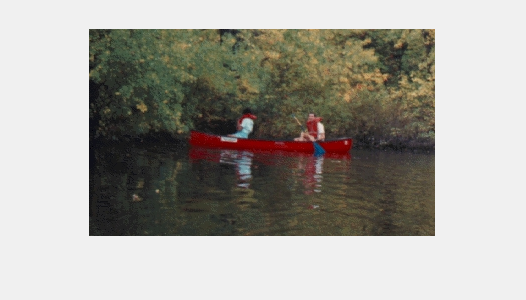

load canoe.jpg
canoe_harkka

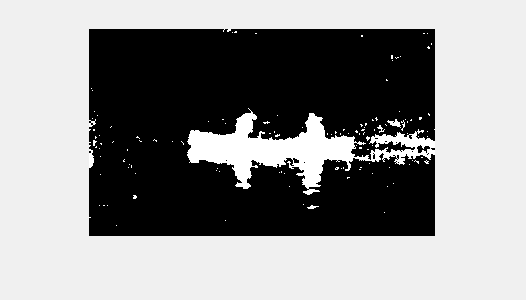

myy1=mean(X1);
myy2=mean(X2);
C1 = cov(X1);
C2 = cov(X2);
w = inv(C1+C2)*transpose(myy1-myy2);
myy1_proj = myy1*w;
myy2_proj = myy2*w;
c = mean([myy1_proj,myy2_proj]);
Z = imlincomb(w(1), img(:,:,1), w(2), img(:,:,2), w(3), img(:,:,3));
imshow(Z > c, [])